clear all;
load sequence_heart2_train.mat;

time_series_data = sequence;

min(sequence)

ans = 3

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       16.52% |       16.52% |       2.3110 |       2.2379 |          0.0010 |
|      50 |          50 |       00:00:07 |       54.38% |       53.71% |       1.2549 |       1.2497 |          0.0010 |
|======================================================================================================================|
Training finished: Max epochs completed.


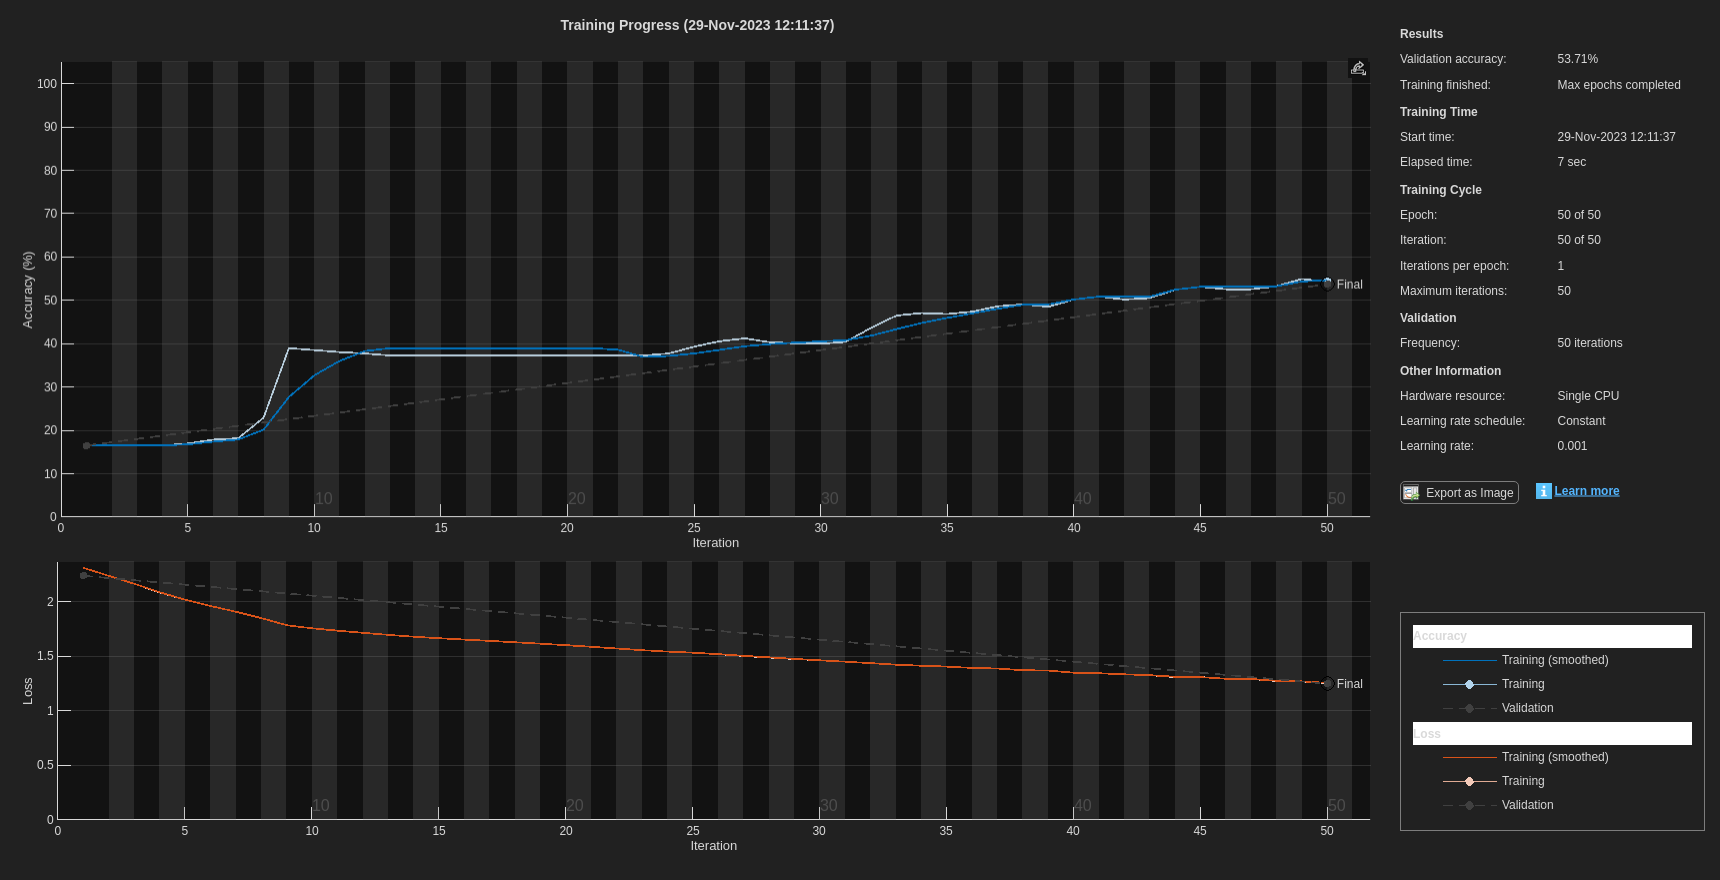

% Assuming you have a 1D time series data named 'time_series_data'
sequence_length = 10;  % Length of input sequences
num_samples = length(time_series_data) - sequence_length;

% Create sequences
X = zeros(sequence_length, num_samples);
y = zeros(1, num_samples);

for i = 1:num_samples
    X(:, i) = time_series_data(i:i+sequence_length-1);
    y(i) = time_series_data(i+sequence_length);
end

% Reshape the input data for LSTM
X = permute(X, [1, 2, 3]);  % [10, num_samples, 1]

% Build the modified LSTM model with 9 output neurons
numUnits = 50;
numClasses = 7;  % Number of output classes

layers = [
    sequenceInputLayer(sequence_length)
    lstmLayer(numUnits, 'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
];

% Training options (modify as needed)
options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'ValidationData', {X, categorical(y)}, ...  % Use categorical labels for classification
    'Plots', 'training-progress');

% Train the modified LSTM model
net = trainNetwork(X, categorical(y), layers, options);

dataset = [1; 2; 3; 4; 5; 6; 7; 8; 9; 10];

sequenceLength = initializeSymbolMachine('sequence_heart2_test.mat',0);

Initialized Symbol Machine for sequence_heart2_test.mat, which contains 900 symbols.
Use symbolMachine.m to make forecasts.



probs = [1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9 1/9];
for ii = 1 : 10
    [dataset(ii), penalty] = symbolMachine(probs);
end
for jj = 11:sequenceLength
    probs = predict(net, dataset);
    for ii = 1:7
        probs((10-ii)) = probs((8-ii));
    end
    probs(1) = 1/9;
    probs(2) = 1/9;
    probs = probs/(sum(probs));
    for ii = 1 : 9
        dataset(ii) = dataset(ii+1);
    end
    [dataset(10), penalty] = symbolMachine(probs);
end
reportSymbolMachine;

SYMBOL MACHINE REPORT (EMAIL TO PROF WAKIN FOR LEADERBOARD)
Processed 900 out of 900 symbols in sequence_heart2_test.mat.
Total penalty: 2457.731 bits (2.7308 bits per symbol).
        0 probabilities forecasted between 0.0000 (Inf bits) and 0.0039 (8 bits).
        0 probabilities forecasted between 0.0039 (8 bits) and 0.0078 (7 bits).
        0 probabilities forecasted between 0.0078 (7 bits) and 0.0156 (6 bits).
        0 probabilities forecasted between 0.0156 (6 bits) and 0.0312 (5 bits).
     1956 probabilities forecasted between 0.0312 (5 bits) and 0.0625 (4 bits); actual occurrence rate 0.0005.
     2747 probabilities forecasted between 0.0625 (4 bits) and 0.1250 (3 bits); actual occurrence rate 0.0619.
     3319 probabilities forecasted between 0.1250 (3 bits) and 0.2500 (2 bits); actual occurrence rate 0.2124.
       78 probabilities forecasted between 0.2500 (2 bits) and 0.5000 (1 bits); actual occurrence rate 0.3077.
        0 probabilities forecasted between 0.5000 (1 bits